# Focusing via Shrinking

## Introduction

Traditional scanning apparatus involves the raster scanning of a focus spot. However, such a method involves in the distortion of the focus spot when the focus is off-axis. Here, a method to decrease the distortion is simulated.

close all;

% add path to find function scripts
addpath('./Functions');

## Setup

### Physical Setup

A beam in the 0.3 Terahertz region would be considered. This means a wavelength of 1mm. It would be propagated across a distance of 20mm. The size of the antenna would be a square of 12mmx12mm. 

### Simulation Setup

The plane would be discretized into a grid of 512x512 points. Both planes are of 50mmx50mm.

% setup

lambda = 1e-3;
k0 = 2*pi/lambda;
z = 20e-3;
antenna_r = 6e-3;

L = 50e-3;
M = 512;
dx = L/M;
x = dx*(-M/2:M/2-1);
y = dx*(-M/2:M/2-1);
[X, Y] = meshgrid(x, y);


## Propagation

### Theory

A scanning system involving an antenna plane and a focal plane would be considered. In this system, the two planes lie perpendicular to the z axis, and are parallel to each other. To simulate the propagation of a beam, the Angular Spectrum Method (ASM) would be employed. This involves decomposing the initial field on the antenna plane into its constituents frequency components via Fourier Transform and propagating each component across the z axis onto the focal plane. To do this, the frequency spectrum is multiplied by a propagator defined by $exp(-ik_0z\sqrt{1-(\lambda f_x)^2-(\lambda f_y)^2})$. Evanescent components, which satisfy $fx^2+fy^2 > 1$, decays after a few wavelengths, and can simply be set as 0. Then, the inverse Fourier Transform is performed to recover the field at the focal plane.

### Simulation

An initial field is defined to be: 


$$E_0(x,y,z=z_0) = \exp{ik_0\sqrt{(x-x_0)^2 + (y-y_0)^2 + z^2}}$$$
 

Where $z_0$ is the distance between the planes, and $k_0$ is the wavevector defined as $k_0 = \frac{2\pi}{\lambda}$. The constants $x_0, y_0$ defines where the focus spot is located at on the plane. This can be made a function of angle $\phi, \theta$ which determines where the beam is 'aimed'. In the simulation, the field is first defined, and then windowed to produce the effect of a 6mmx6mm antenna which launches the beam.

x_angle = 0;
y_angle = 0;
x_offset = z*tand(x_angle);
y_offset = z*tand(y_angle);


uo = exp(1i*k0*sqrt((X-x_offset).^2 + (Y-y_offset).^2 + z^2));
uo(abs(y) > antenna_r, :) = 0;
uo(:, abs(x)>antenna_r) = 0;

% figure('Name', 'Antenna Plane')
% imagesc(x/1e-3, y/1e-3, angle(uo));
% xlabel('mm');
% ylabel('mm');
% apc = colorbar;
% apc.Label.String = "Phase in radians";
% colormap jet;
% axis square;

This field is then propagated:

u1 = propTF(uo, L, lambda, z);

% figure('Name', 'Focal Plane');
% imagesc(x/1e-3, y/1e-3, abs(u1));
% xlabel('mm');
% ylabel('mm');
% apc = colorbar;
% apc.Label.String = "Amplitude";
% colormap jet;
% axis square;

## Backpropagation

### Theory

It can be shown that back propagating the wave is given by the inverse of the propagator function, which is also equal to simply rewriting the propagator from $z$ to $-z$, and so: $exp(-ik_0z\sqrt{1-(\lambda f_x)^2-(\lambda f_y)^2})$, where $z$ is the distance between the two planes. 

### Simulation

A brief demonstration can show the effectiveness of the method. The field distribution derived above is backpropagated onto the antenna plane. This can then be compared with the field distribution that was defined. 

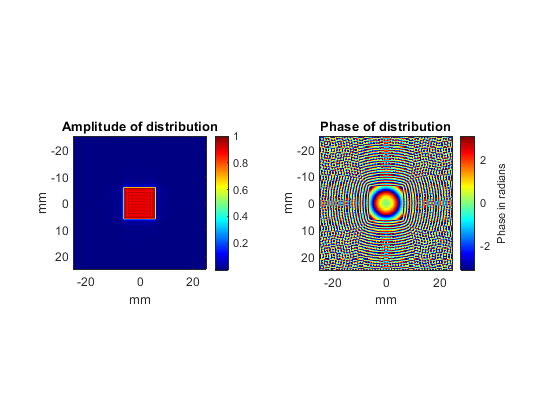

demo_u0 = backpropTF(u1, L, lambda, z);

figure('Name', "Antenna Plane")
subplot(121);
imagesc(x/1e-3, y/1e-3, abs(demo_u0)/max(max(abs(demo_u0))));
title('Amplitude of distribution');
xlabel("mm");
ylabel("mm");
colorbar;
axis square;
colormap jet;

subplot(122);
imagesc(x/1e-3, y/1e-3, angle(demo_u0));
title("Phase of distribution")
xlabel("mm");
ylabel("mm");
demo_c = colorbar;
demo_c.Label.String = "Phase in radians";
axis square;
colormap jet;

Check that the difference in the region of interest (antenna dimensions) is acceptable.

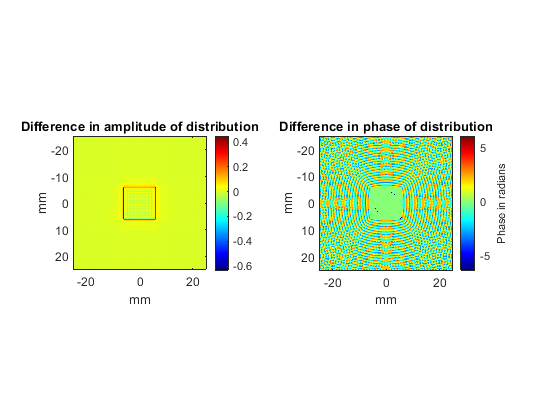

figure('Name', "Antenna Plane")
subplot(121);
imagesc(x/1e-3, y/1e-3, abs(demo_u0)-abs(uo));
title('Difference in amplitude of distribution');
xlabel("mm");
ylabel("mm");
colorbar;
axis square;
colormap jet;

subplot(122);
imagesc(x/1e-3, y/1e-3, angle(demo_u0)-angle(uo));
title("Difference in phase of distribution")
xlabel("mm");
ylabel("mm");
demo_c = colorbar;
demo_c.Label.String = "Phase in radians";
axis square;
colormap jet;

## Distortion

### Theory

Distortion would now be discussed. In the preceeding sections, the focus point is located at the center. In a scanning system, a method such as raster scanning may be employed, and this would require the focus point to travel around a rectangular region that is larger than the antenna dimensions. The focus point at the antenna plane can be defined to not focus at the center, but at any off-axis point. However, this results in the distortion of the focus point. The point would appear elongated and stretched. Simulation shows that such a distortion increases with the angle the focus is away from the propagation axis, and at the same angle it increases with the propagation distance. This agrees with intuitive expectations about the system.

### Simulation

To demonstrate, plots of the focus point at different angles are shown. The antenna aperture can also be varied. Notice that as the aperture size grows, the spot becomes smaller, which might be caused by diffraction around the aperture. This also means that as aperture size decreases, the distortion increases.

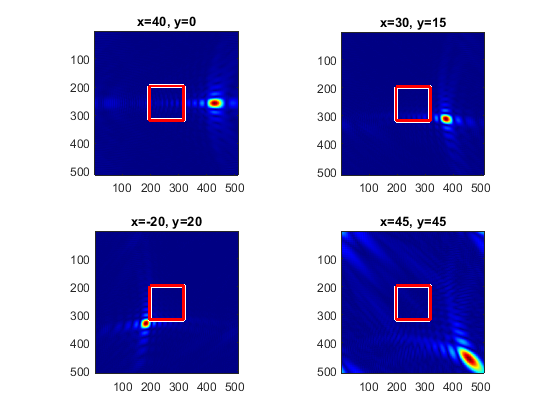

angle_list = [40 0;30 15;-20 20;45 45];
antenna_r = 0.006;

figure('Name', 'Distortion')
for i = 1:length(angle_list)
    u0 = rect_parabolic(angle_list(i,1), angle_list(i,2), antenna_r, lambda, x, y, z);
    bd = zeros(size(u1));
    bd(u0~=0) = true;
    u1 = propTF(u0, L, lambda, z);
    
    subplot(2,2,i);
    imagesc(abs(u1));
    hold on;
    visboundaries(gca, bd);
    hold off;
%     xlabel("mm");
%     ylabel("mm");
    title(['x=',num2str(angle_list(i,1)),', y=', num2str(angle_list(i,2))]);
    colormap jet;
    axis square;
end

### Reducing Distortion

One way of reducing the distortion would simply be backpropagating a desired focused field back onto the antenna plane. For example, it would be desirable to have focus points across the plane to be identical to the round, undistorted central focus point. As such, an easy way to achieve this is to first have the field with the central focus point and 'operate' on it by shifting this central point onto a desired location on the focal plane. Then, backpropagate this onto the antenna plane, before windowing this distribution so the antenna can propagate it again.

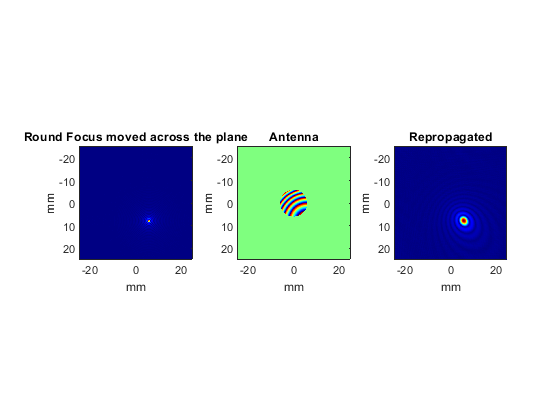

antenna_r = 6e-3;
centerfield = propTF(circ_parabolic(0,0,L/2,lambda,x,y,z),L,lambda,z);
% centerfield(X.^2+Y.^2 > (5e-4)^2) = 0;
centerfield = circshift(centerfield,[80 60]);



u0 = backpropTF(centerfield, L, lambda, z);
u0(X.^2 + Y.^2 > antenna_r^2) = 0;
u1 = propTF(u0, L, lambda, z);

figure('Name', 'Perfect Focus');
subplot(131);
imagesc(x/1e-3, y/1e-3, abs(centerfield));
colormap jet;
axis square;
xlabel("mm");
ylabel("mm");
title("Round Focus moved across the plane");

subplot(132);
imagesc(x/1e-3, y/1e-3, angle(u0));
colormap jet;
axis square;
xlabel("mm");
ylabel("mm");
title("Antenna");

subplot(133);
imagesc(x/1e-3, y/1e-3, abs(u1));
colormap jet;
axis square;
xlabel("mm");
ylabel("mm");
title("Repropagated");

If the focal plane is windowed before hand, the results may be even better.

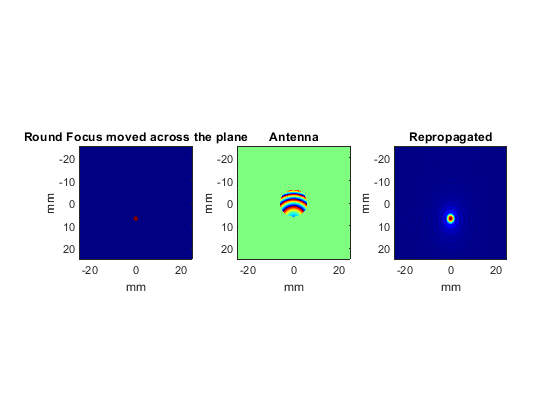

antenna_r = 6e-3;
centerfield = ones(M);
centerfield(X.^2+Y.^2 > (10*dx)^2) = 0;
centerfield = circshift(centerfield,[70 0]);



u0 = backpropTF(centerfield, L, lambda, z);
u0(X.^2 + Y.^2 > antenna_r^2) = 0;
u1 = propTF(u0, L, lambda, z);

figure('Name', 'Perfect Focus');
subplot(131);
imagesc(x/1e-3, y/1e-3, abs(centerfield));
colormap jet;
axis square;
xlabel("mm");
ylabel("mm");
title("Round Focus moved across the plane");

subplot(132);
imagesc(x/1e-3, y/1e-3, angle(u0));
colormap jet;
axis square;
xlabel("mm");
ylabel("mm");
title("Antenna");

subplot(133);
imagesc(x/1e-3, y/1e-3, abs(u1));
colormap jet;
axis square;
xlabel("mm");
ylabel("mm");
title("Repropagated");